**Ex 2.2.1 a)**

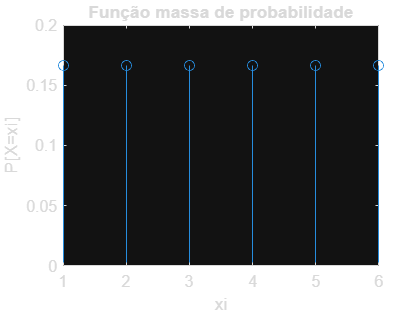

Sx = 1:6; %espaço de amostragem

prob = ones(1,6)/6;

stem(Sx,prob);
title("Função massa de probabilidade");
xlabel('xi');
ylabel('P[X=xi]');

%axis([0 7 0 1/5]);

**Ex 2.2.1 b)**

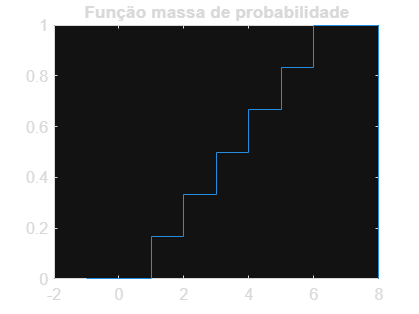

Sx = 1:6; %espaço de amostragem

prob = ones(1,6)/6;

px = cumsum(prob);
stairs([-1 Sx 8], [0 px 0])
title("Função massa de probabilidade");

%axis([-1 8 0 1.1]);

**Ex 2.2.2 a)**

Espaço de amostragem = valor das notas (nota1, nota2, ..., nota100)

P(5euros) = 90/100

P(50euros) = 9/100

P(100euros) = 1/100

**Ex 2.2.2 b)**

X = [5 50 100];
prob = [90 9 1]/100;

stem(X, prob);
axis([0 105 0 1]);
grid on

**Ex 2.2.2 c)**

X = [5 50 100];
prob = [90 9 1]/100;

px = cumsum(prob);
stairs([0 X 101], [0 px 1]);
axis([0 101 0 1.1]);
grid on

**Ex 2.2.3 a)**

%Sx = 0:4;

N = 1e5;
p = 1/2;
expe = rand(4, N) < p;

num0 = sum(sum(expe) == 0);
num1 = sum(sum(expe) == 1);
num2 = sum(sum(expe) == 2);
num3 = sum(sum(expe) == 3);
num4 = sum(sum(expe) == 4);

prob0 = num0/N;
prob1 = num1/N;
prob2 = num2/N;
prob3 = num3/N;
prob4 = num4/N;

fprintf("Px(0)= %.6f\nPx(1)= %.6f\nPx(2)= %.6f\nPx(3)= %.6f\nPx(4)= %.6f\n", prob0,prob1,prob2,prob3,prob4);

Px(0)= 0.062860
Px(1)= 0.251520
Px(2)= 0.376610
Px(3)= 0.247010
Px(4)= 0.062000


**Ex 2.2.3 b)**

Sx = 0:4;

N = 1e5;
p = 1/2;
exp1 = rand(4, N) < p;

num0 = sum(sum(exp1) == 0);
num1 = sum(sum(exp1) == 1);
num2 = sum(sum(exp1) == 2);
num3 = sum(sum(exp1) == 3);
num4 = sum(sum(exp1) == 4);

prob0 = num0/N;
prob1 = num1/N;
prob2 = num2/N;
prob3 = num3/N;
prob4 = num4/N;

probs = [prob0 prob1 prob2 prob3 prob4]

media = sum(Sx.*probs);
var = sum((Sx.^2).*probs) - (media.^2);
desvio_padrao = sqrt(var);

fprintf("Valor Esperado = %.6f \nVariância = %.6f \nDesvio padrão = %.6f\n", media, var, desvio_padrao)

**Ex 2.2.4 a) i. & ii.**

O que está comentado é para o ex i.

Sx = 0:5;
N = 1e5;

defeito = rand(5, N) < 0.3;

defeito0 = sum(sum(defeito) == 0);
defeito1 = sum(sum(defeito) == 1);
defeito2 = sum(sum(defeito) == 2);
defeito3 = sum(sum(defeito) == 3);
defeito4 = sum(sum(defeito) == 4);
defeito5 = sum(sum(defeito) == 5);

prob0 = defeito0/N;
prob1 = defeito1/N;
prob2 = defeito2/N;
prob3 = defeito3/N;
prob4 = defeito4/N;
prob5 = defeito5/N;


probs = [prob0 prob1 prob2 prob3 prob4 prob5];

probs1 = cumsum(probs),
%stem(Sx, probs);
stairs([-1 Sx 6], [0 probs1 1]) % ii.
%axis = ([-1 6 0 0.5])
axis = ([-1 6 0 1.2]) % ii.

**Ex 2.2.4 b)**

Sx = 0:5;
N = 1e5;
p = 0.3;

defeito = rand(5, N) < p;

defeitomax2 = sum(sum(defeito) <= 2);   

pmax2 = defeitomax2/N;

fprintf("%0.6d", pmax2)

**Ex 2.2.5**

N = 1e5;
falha2 = rand(2,N) < 0.3;
falha4 = rand(4, N) < 0.3;

cair2 = sum(sum(falha2) > 1);
cair4 = sum(sum(falha4) > 1);

probCair2 = cair2/N
probCair4 = cair4/N


## Gráfico 2.2.5

p = logspace(-3, log10(1/2), 100)

prob2 = zeros(1, 100)
prob4 = zeros(1, 100);

i = 1;

for f = p
    prob2(i) = prob_teorica(2,2,f);
    prob4(i) = prob_teorica(3,4,f) + prob_teorica(4,4,f);
    i = i + 1;
end

plot(p, prob2);
hold on
plot(p, prob4),
hold off

legend('2 motores', '4 motores');

**Ex 2.2.6 a)**

A dsitribuição de Poisson é uma forma limite da distribuição binomial (quando n -> ∞ , p -> 0 e np permanece constante).

Pode ser usada para aproximar e simplificar os cálculos envolvidos com a binomial em situações em que as condições anteriores se verifiquem.

probt = prob_teorica(7, 8000, 0.001);

fprintf("%0.3d", probt);

1.396e-01

**Ex 2.2.6 b)**

lambda = 8000 * 0.001;
k = 7;

pk = ((lambda ^ k) / factorial(k)) * exp(-lambda);
fprintf("%0.3d", pk)

1.396e-01

**Ex 2.2.7 a)**

lambda = 15;
k = 0;

pka = ((lambda ^ k) / factorial(k)) * exp(-lambda);

**Ex 2.2.7 b)**

lambda=15;
soma = 0;

for k = 0:10 
    pkb = ((lambda^k)/factorial(k))*exp(-lambda);
    soma = pkb + soma;
end

resultado = 1 - soma

resultado = 0.8815

**Ex 2.2.8**

lambda=0.02*100;
pk=0;

for k = 0:1
    pk = pk + ((lambda^k)/factorial(k))*exp(-lambda);
end 

disp(pk);

    0.4060



**Ex 2.2.9 a)**

N = 1e5;
media = 14;
desvio = 2;

X = randn(1, N);
Y = X * desvio + media

Y =    15.0892   14.8041   13.4547   11.5519   15.2723   11.4956   10.7839   13.4860   13.2771   12.4682   12.7832   12.8083   13.8131   12.4253   14.7486   17.4048   12.7585   14.1674   11.9614   11.9705   12.4293   16.5463   11.7206   13.9759   12.5393   12.2700   17.1642   17.2186   13.2017   12.3653   11.7836   14.9996   12.2007   11.7509   15.0308   18.8474   14.2952   12.3388   15.5087   11.7269   14.4946   13.0037    8.1494   15.5361   12.5712   16.0567   13.8484   13.9003   13.4332   15.2921



notas12a16 = sum (Y > 12 & Y < 16);
prob12a16 = notas12a16/N

prob12a16 = 0.6815


prob_teo_12a16 = normcdf(16,media,desvio) - normcdf(12,media,desvio)

prob_teo_12a16 = 0.6827

**Ex 2.2.9 b)**

N = 1e5;
media = 14;
desvio = 2;

X = randn(1, N);
Y = X * desvio + media

Y =    13.1353   12.7547   12.5444   11.1349   14.5043   10.9083   15.0259   12.0625   14.3792   14.2202   11.6884   15.9854   13.0497   15.5343   12.3343   18.3686   15.1258   14.7774   11.9343   11.6747   13.9453   13.9388   13.9507   16.6314   12.4885   12.5803   13.3478   13.3520   11.7832   13.7736   14.5955   11.1206   15.0351   12.2986   12.2260   14.0347   13.9108   12.4407   12.6772   10.0252   12.9177   12.1063   12.2872   13.2099   14.5320   13.6911   12.5011   17.7835   13.8133   15.6161



notas10a18 = sum (Y > 10 & Y < 18);
prob10a18 = notas10a18/N

prob10a18 = 0.9548


prob_teo_10a18 = normcdf(18,media,desvio) - normcdf(10,media,desvio)

prob_teo_10a18 = 0.9545

**Ex 2.2.9 c)**

N = 1e5;
media = 14;
desvio = 2;

X = randn(1,N);
Y = X * desvio + media;

notas10 = sum( Y >= 10);
prob10 = notas10/N

prob10 = 0.9770


prob_teo_10 = 1 - normcdf(10,14,2)

prob_teo_10 = 0.9772